clf

Movements = [linspace(19,10,90),linspace(10,-10,200),linspace(-10,-13,30),linspace(-13,-13,30),linspace(-13,-13,30); linspace(14,14,90),linspace(14,-12,200),linspace(-12,-12,30),linspace(-12,0,30),linspace(0,-12,30)]

Movements =    19.0000   18.8989   18.7978   18.6966   18.5955   18.4944   18.3933   18.2921   18.1910   18.0899   17.9888   17.8876   17.7865   17.6854   17.5843   17.4831   17.3820   17.2809   17.1798   17.0787   16.9775   16.8764   16.7753   16.6742   16.5730   16.4719   16.3708   16.2697   16.1685   16.0674   15.9663   15.8652   15.7640   15.6629   15.5618   15.4607   15.3596   15.2584   15.1573   15.0562   14.9551   14.8539   14.7528   14.6517   14.5506   14.4494   14.3483   14.2472   14.1461   14.0449
   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0000   14.0

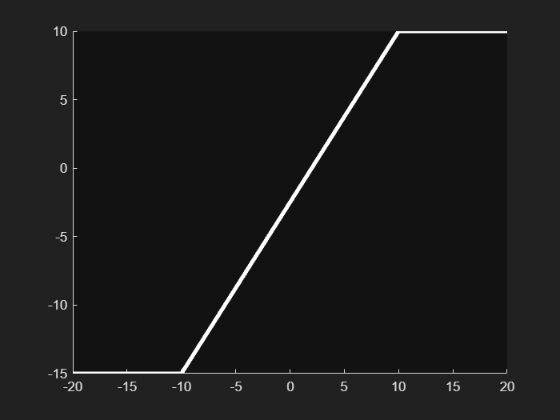

Rotated by rot_1


Rotated by rot_2



penguin = [8,8,8,7.5,7,5.5,4,1,3,3,2.5,2,1.5,1.5,2,4,6,8,6,7,7,6.5,6,5.5,4.5,4.25,5,6,5,3; 1,9,11,13,14,15,14,14,12,11,10,9,6,4,2,1,1,1,1,3,4,6,5,4.75,4.5,5,7,9,10.5,11; 1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1];
slope = [20,10,-10,-20;10,10,-15,-15];

%Variables
xdist = 0;
ydist = 0;
count_1 = 0;
count_2 = 0;
rot_1 = deg2rad(140);
rot_2 = deg2rad(-140);

%Initiators
wide_axes = [-20 20 -20 20];
start_pos = [1,0,15;0,1,10;0,0,1];
shrink_start = [.5,0,0;0,.5,0;0,0,1];
penguin = shrink_start * penguin;
penguin = start_pos * penguin;

%Moves
translate = [1,0,0;0,1,0;0,0,1];
OG_translate = [1,0,0;0,1,0;0,0,1];

f=figure ('Visible', 'on'); 
hold on;

for step = 1: length(Movements)
hold on
plot(slope(1,:),slope(2,:), "w",'LineWidth',3);
hold off

    translate = OG_translate;

    xdist = - penguin(1,27) + Movements(1,step);
    ydist = - penguin(2,27) + Movements(2,step);
    
    if (penguin(1,27) <= 10) && (count_1 < 1)
        penguin = [1,0,10;0,1,15;0,0,1] * penguin;
        penguin = [cos(rot_1),-sin(rot_1),0;sin(rot_1),cos(rot_1),0;0,0,1] * penguin;
        penguin = [1,0,-10;0,1,-15;0,0,1] * penguin;
        count_1 = 1;
        count_2 = count_2 - 1;
        fprintf('Rotated by rot_1\n');
    elseif (penguin(1,27) < -10) && (step > 300) && (count_2 < 1)
        penguin = [1,0,10;0,1,15;0,0,1] * penguin;
        penguin = [cos(rot_2),-sin(rot_2),0;sin(rot_2),cos(rot_2),0;0,0,1] * penguin;
        penguin = [1,0,-10;0,1,-15;0,0,1] * penguin;
        count_2 = 1;
        fprintf('Rotated by rot_2\n');
    end

    

    translate(1,3) = xdist;
    translate(2,3) = ydist;
    
    penguin = translate * penguin;
    pause(0.005);
    plot(penguin(1,:),penguin(2,:), "w",'LineWidth',2);
    axis(wide_axes);

    xdist = xdist * 0;
    ydist = ydist * 0;

end

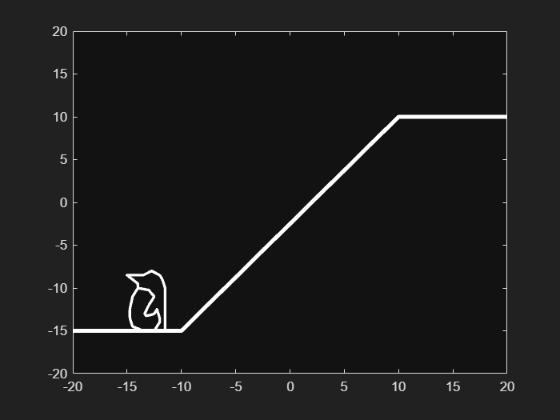


hold on
plot(penguin(1,:),penguin(2,:), "w",'LineWidth',2);
plot(slope(1,:),slope(2,:), "w",'LineWidth',3);